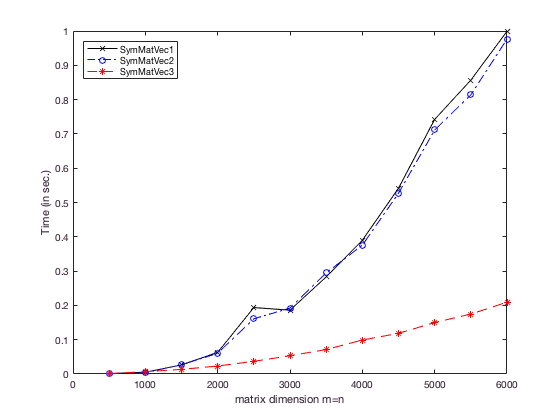

output
close all

plot( data_SymMatVec1( :,1 ), data_SymMatVec1( :, 2 ), 'k-x' ); 

hold on    % Plot additional data in same figure

plot( data_SymMatVec4( :,1 ), data_SymMatVec4( :, 2 ), 'b-.o' ); 
plot( data_SymMatVec5( :,1 ), data_SymMatVec5( :, 2 ), 'r--*' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n' );
ylabel( 'Time (in sec.)' );
legend( 'SymMatVec1', ...
        'SymMatVec2', ...
        'SymMatVec3', 'Location', 'NorthWest' );
 print('SymMatVecTime', '-dpdf')
plot( data_SymMatVec1( :,1 ), data_SymMatVec1( :, 2 ) ./ data_SymMatVec2( :, 2 ), 'k-x' ); 

hold on    % Plot additional data in same figure

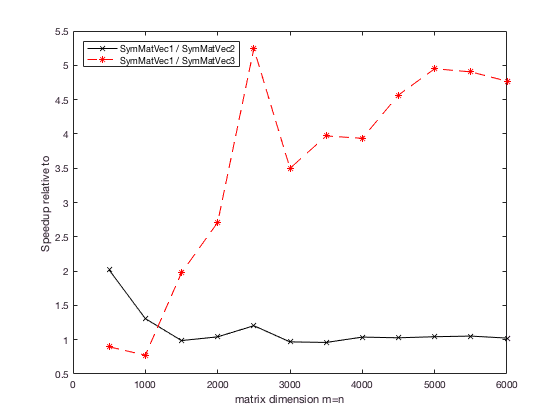


plot( data_SymMatVec3( :,1 ), data_SymMatVec1( :, 2 ) ./ data_SymMatVec3( :, 2 ), 'r--*' ); 

hold off   % Stop plotting additional data in same figure% Plot additional data in same figure

% Add x- and y-axis labels and legend
xlabel( 'matrix dimension m=n' );
ylabel( 'Speedup relative to ' );
legend( 'SymMatVec1 / SymMatVec2', ...
        'SymMatVec1 / SymMatVec3', 'Location', 'NorthWest' );
ns = data_SymMatVec1( :, 1 );                                   % Extract a vector of matrix size.
gflops = 2.0 * ns .* ns ./ data_SymMatVec1( :, 2 ) * 1.0e-9;    % Compute a vector of corresponding GFLOPS/sec from the timing data.
plot( ns, gflops, 'k-x' );                                      % Plot the performance data


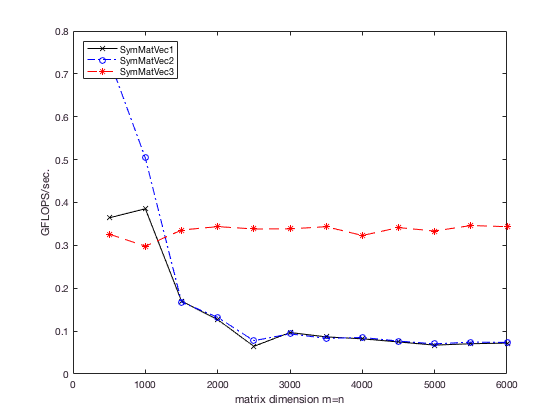

hold on

ns = data_SymMatVec2( :, 1 );
gflops = 2.0 * ns .* ns ./ data_SymMatVec2( :, 2 ) * 1.0e-9;
plot( ns, gflops, 'b-.o' ); 

ns = data_SymMatVec3( :, 1 );
gflops = 2.0 * ns .* ns ./ data_SymMatVec3( :, 2 ) * 1.0e-9;
plot( ns, gflops, 'r--*' ); 

xlabel( 'matrix dimension m=n' );
ylabel( 'GFLOPS/sec.' );
legend( 'SymMatVec1', ...
        'SymMatVec2', ...
        'SymMatVec3', 'Location', 'NorthWest' );